## Quadratic Conjugate Gradient

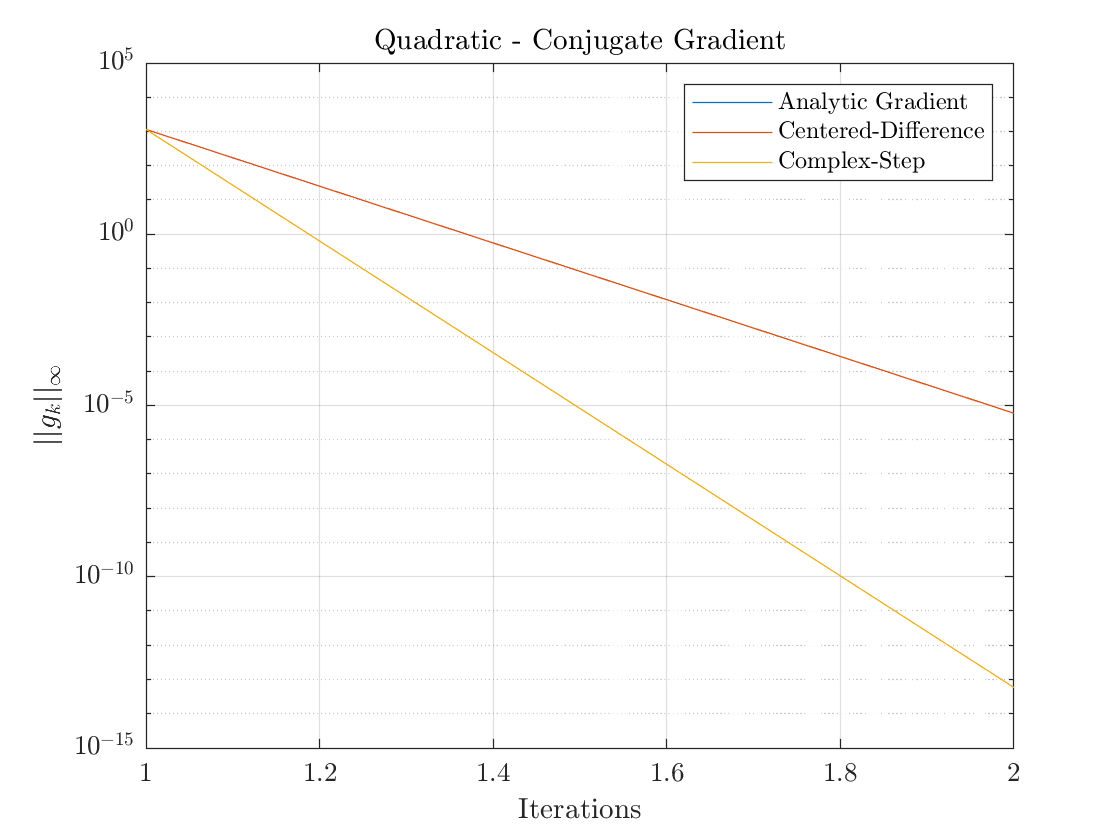

close all
clear
n = 100;
fun = @(x) x.^2;
x0 = rand(1,n)*100;

% Analytic Gradient
gfun = @(x) 2.*x;
[x,fopt,res{1},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Analytic Gradient -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end))) 
% Centered Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Quadratic - Conjugate Gradient", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Matyas Conjugate Gradient

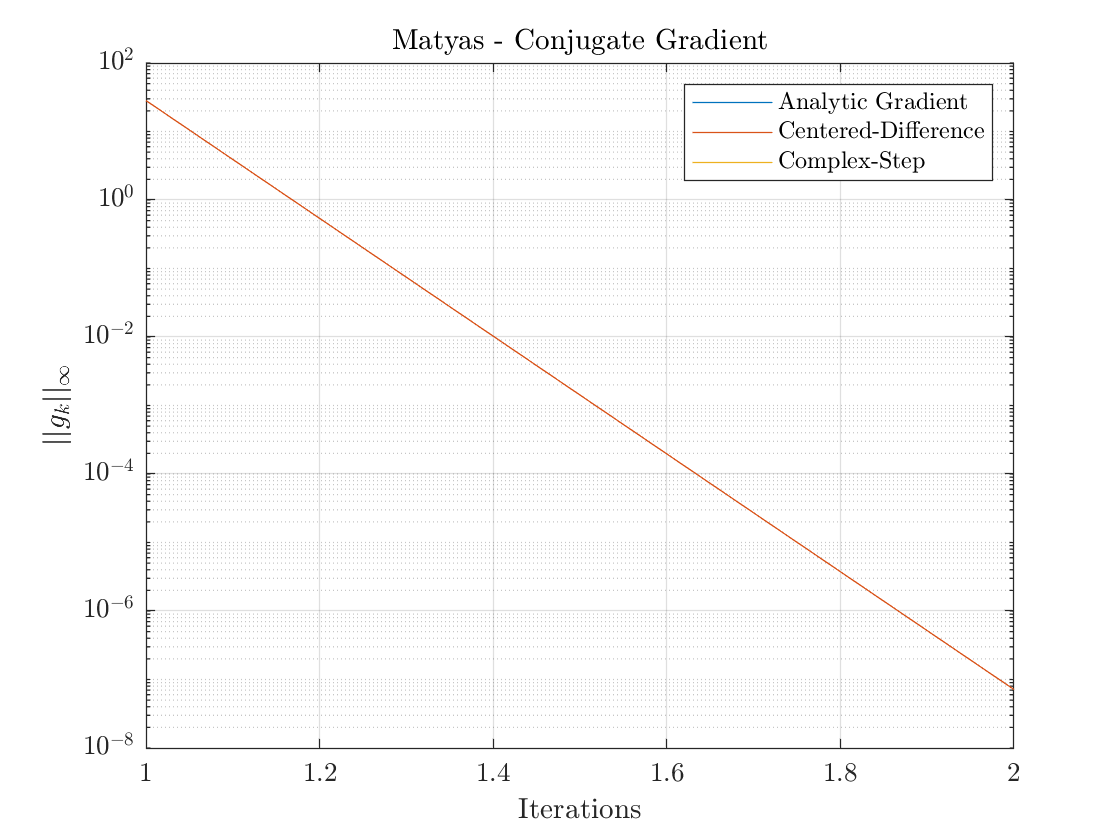

clear
fun = @(x) 0.26 * (x(1)^2 + x(2)^2) - 0.48 * prod(x); 
x0 = [20 -20];

% Analytic Gradient
gfun = @(x) [(13*x(1))/25 - (12*x(2))/25; (13*x(2))/25 - (12*x(1))/25];
[x,fopt,res{1},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Analytic Gradient -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end))) 
% Centered Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Matyas - Conjugate Gradient", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Rosenbrock Conjugate Gradient

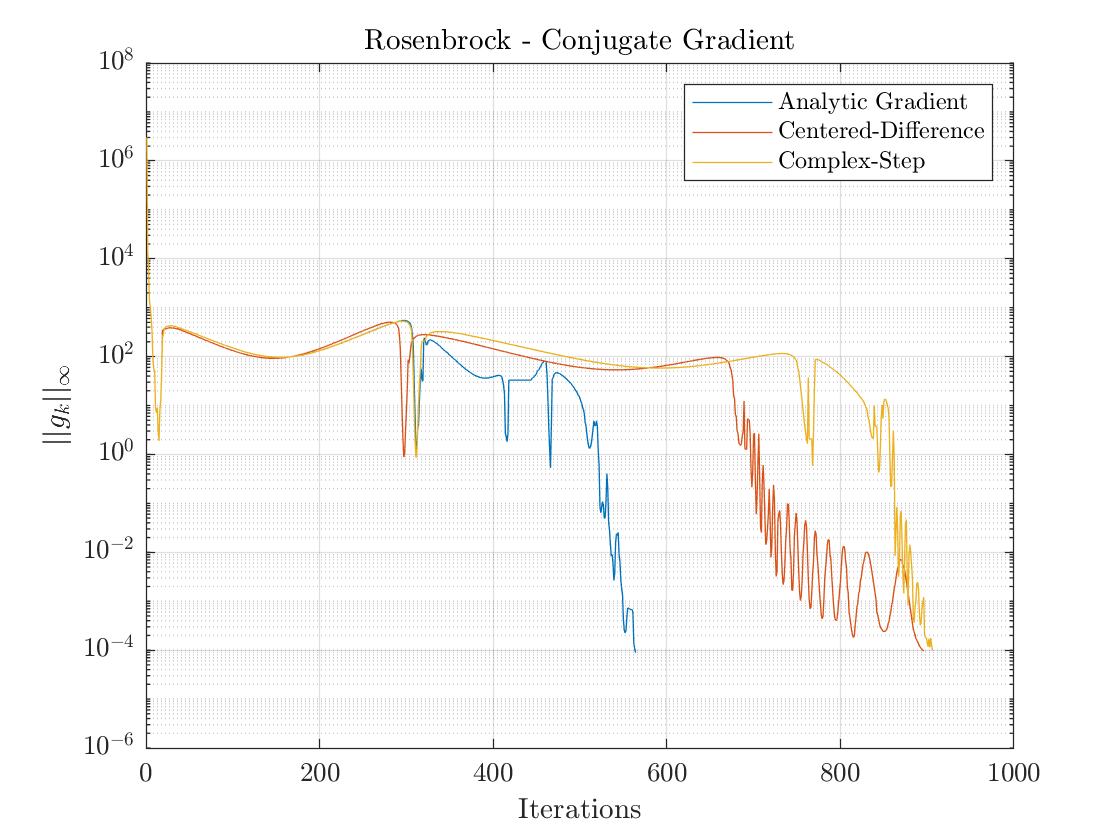

clear
fun = @(x) (1-x(1))^2 + 100 * (x(2) - x(1)^2)^2;
x = sym('x',[1,2],'real');
f(x) = (1-x(1))^2 + 100 * (x(2) - x(1)^2)^2;
g(x) = gradient(f);
% g = @(x) [2*x(1) - 400*x(1)*(- x(1)^2 + x(2)) - 2; -200*x(1)^2 + 200*x(2)]
x0 = [20,20];

% Analytic Gradient
gfun = g;
[x,fopt,res{1},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Analytic Gradient -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Centered Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Rosenbrock - Conjugate Gradient", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Brachistochrone Conjugate Gradient

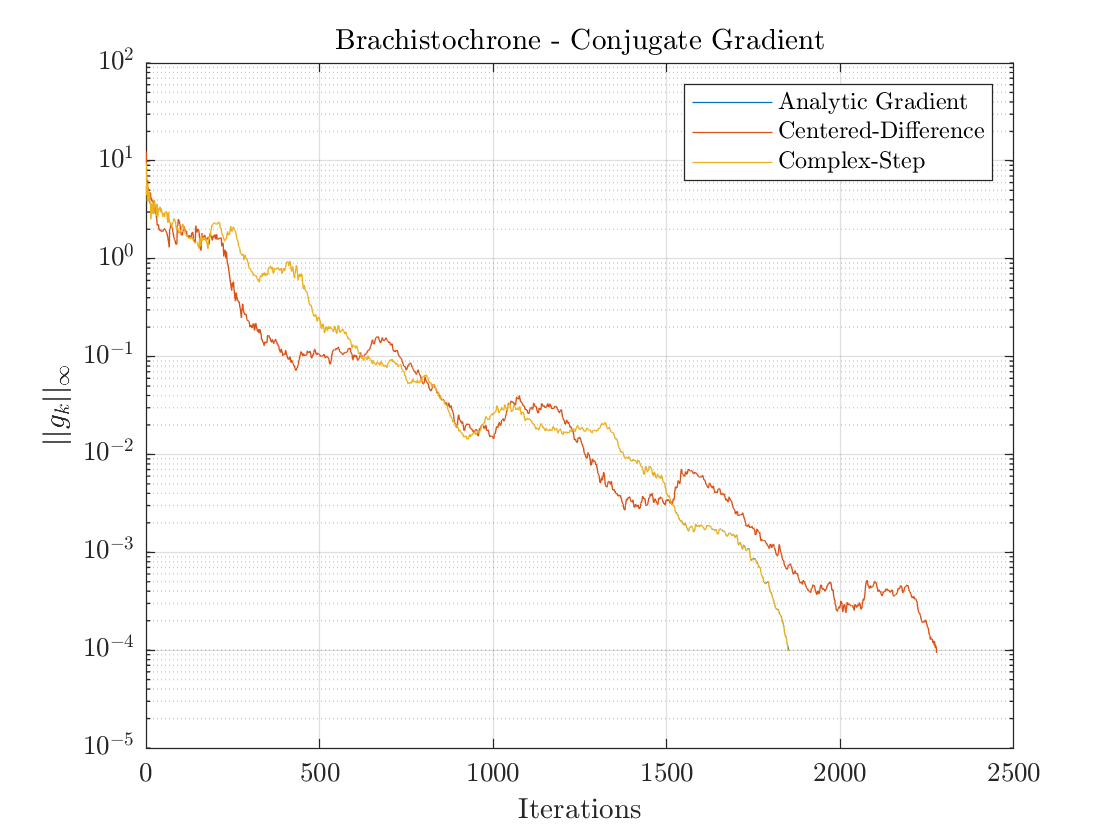

clear
fun = @(x) brachistochrone(x);
x0 = sort(linspace(0,1,128),"descend");

% Integrated Gradient
gfun = "Integrated";
[x,fopt,res{1},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Integrated -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Centered-Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = conjugateGradient(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")%,"MarkerIndices",linspace(1,length(res{1}),10))
plot(res{2},"DisplayName","Centered-Difference")%,"MarkerIndices",linspace(1,length(res{1}),10))
plot(res{3},"DisplayName","Complex-Step")%,"MarkerIndices",linspace(1,length(res{1}),10))
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Brachistochrone - Conjugate Gradient", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Quadratic BFGS

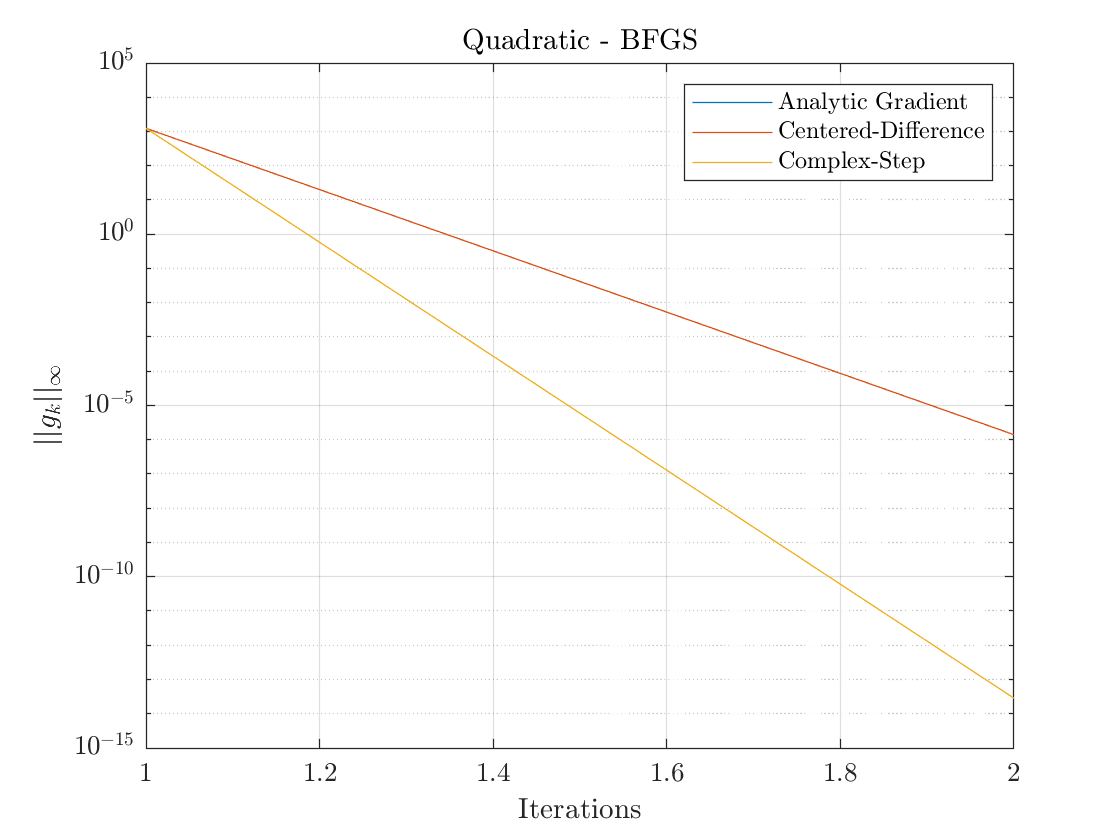

clear
n = 100;
fun = @(x) x.^2;
x0 = rand(1,n)*100;

% Analytic Gradient
gfun = @(x) 2.*x;
[x,fopt,res{1},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Analytic Gradient -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end))) 
% Centered Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Quadratic - BFGS", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Matyas BFGS

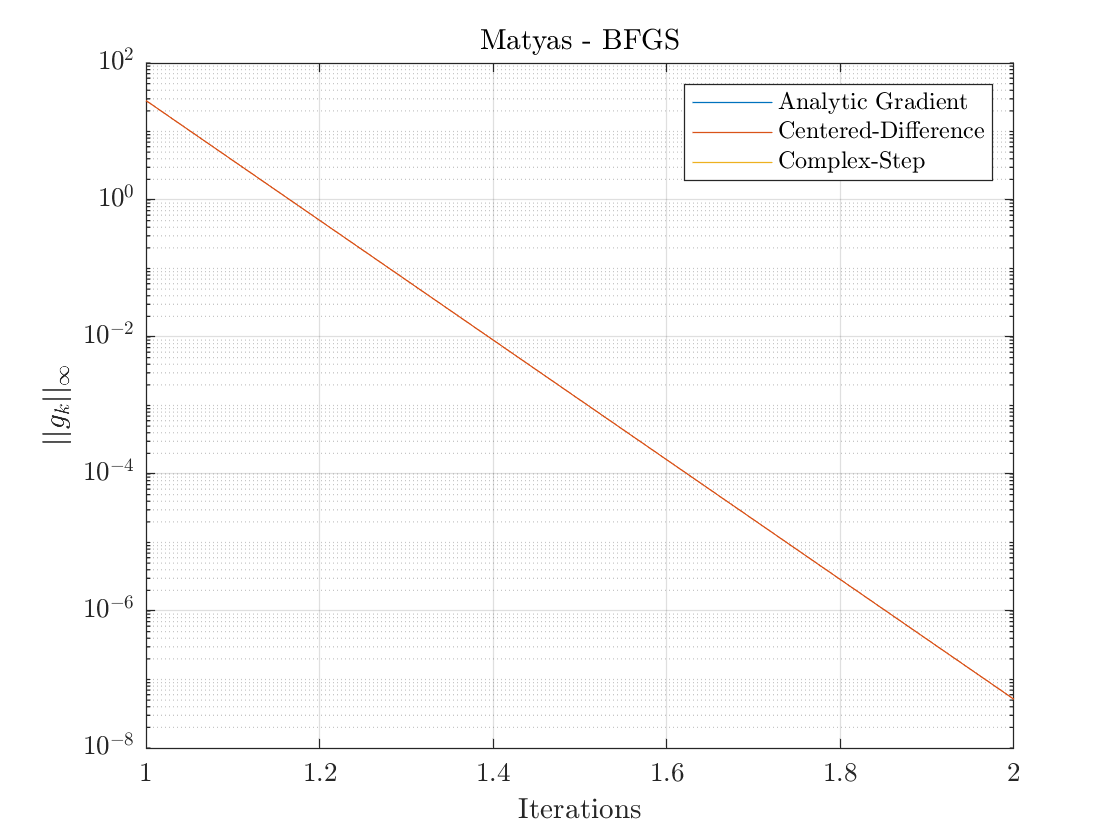

clear
fun = @(x) 0.26 * (x(1)^2 + x(2)^2) - 0.48 * prod(x); 
x0 = [20 -20];

% Analytic Gradient
gfun = @(x) [(13*x(1))/25 - (12*x(2))/25; (13*x(2))/25 - (12*x(1))/25];
[x,fopt,res{1},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Analytic Gradient -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end))) 
% Centered Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-5,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Matyas - BFGS", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Rosenbrock BFGS

clear
fun = @(x) (1-x(1))^2 + 100 * (x(2) - x(1)^2)^2;
x = sym('x',[1,2],'real');
f(x) = (1-x(1))^2 + 100 * (x(2) - x(1)^2)^2;
g(x) = gradient(f);
% g = @(x) [2*x(1) - 400*x(1)*(- x(1)^2 + x(2)) - 2; -200*x(1)^2 + 200*x(2)]
x0 = [20,20];

% Analytic Gradient
gfun = g;
[x,fopt,res{1},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Analytic Gradient -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Centered Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);

Solution Stagnated


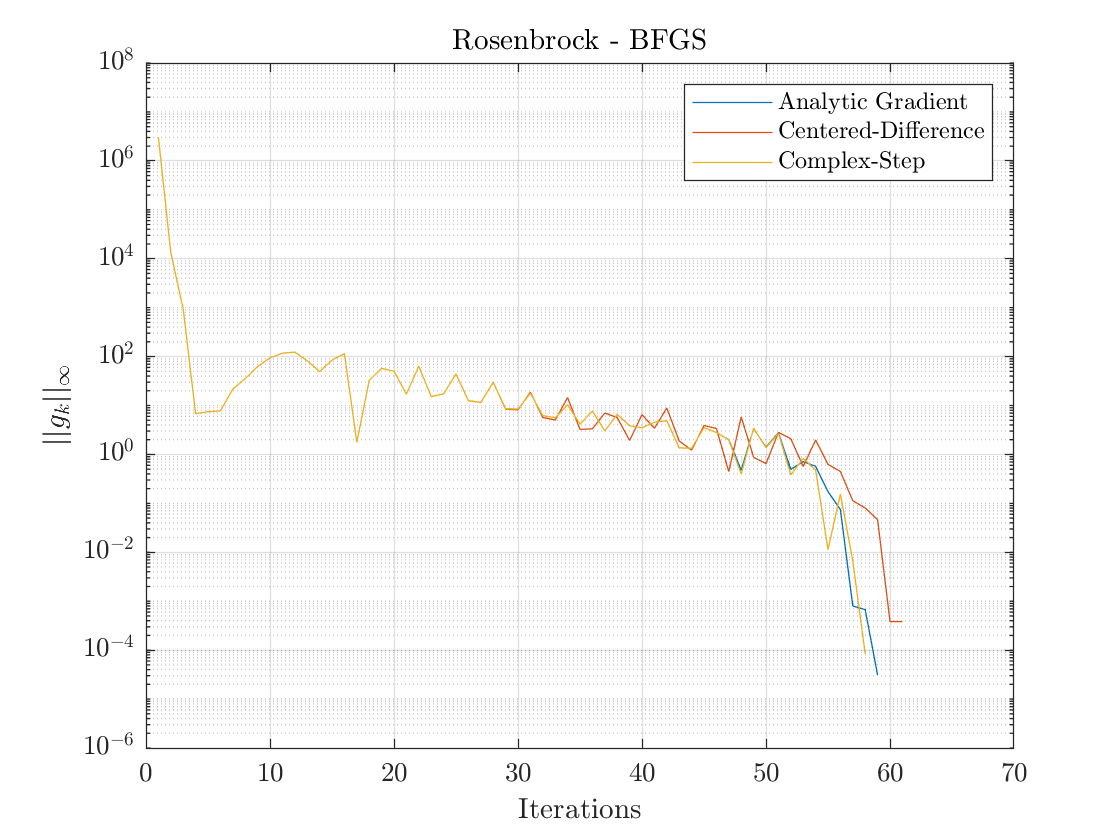

% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Rosenbrock - BFGS", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Brachistochrone BFGS

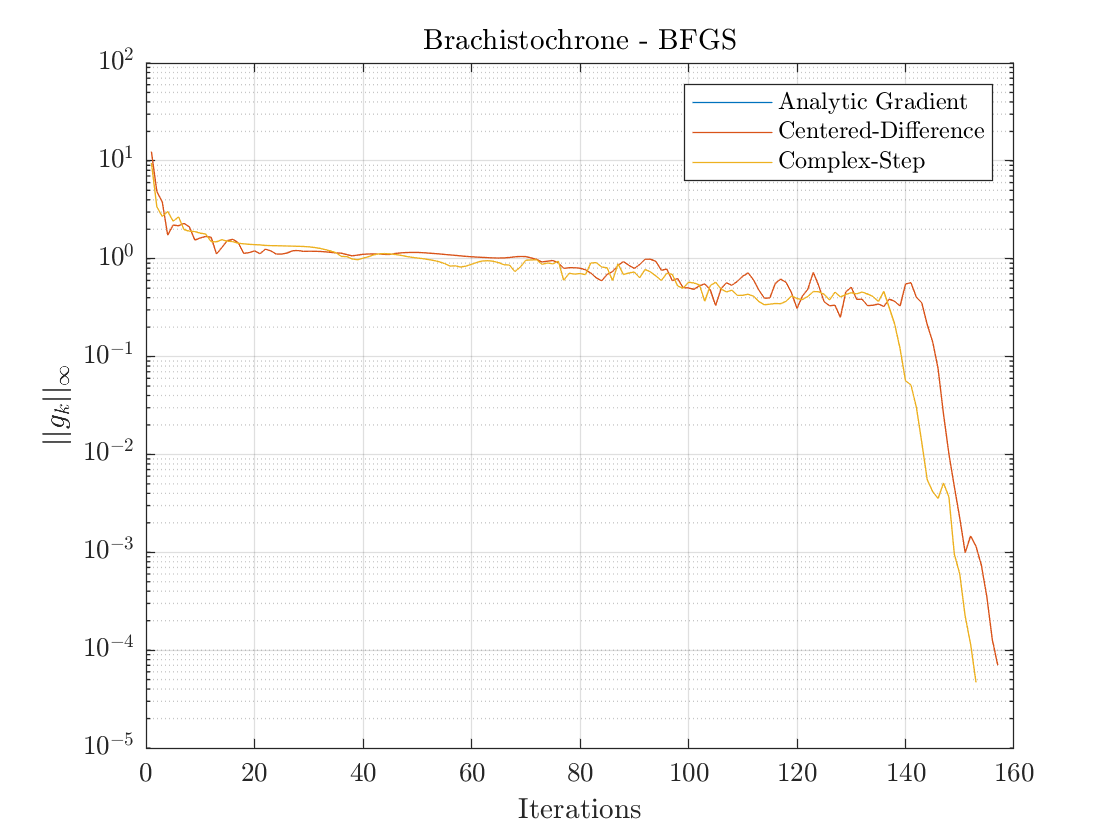

clear
fun = @(x) brachistochrone(x);
x0 = sort(linspace(0,1,128),"descend");

% Integrated Gradient
gfun = "Integrated";
[x,fopt,res{1},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Integrated -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))
% Centered-Difference
gfun = "Centered-Difference";
[x,fopt,res{2},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Centered-Difference -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))
% Complex Step
gfun = "Complex-Step";
[x,fopt,res{3},iter,funEvals] = BFGS(fun,x0,"gradFun",gfun,"nl_tol",1e-4,"max_iter",1e4);
% disp("Complex-Step -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)) + " Residual = " + num2str(res(end)))

figure
hold on
plot(res{1},"DisplayName","Analytic Gradient")
plot(res{2},"DisplayName","Centered-Difference")
plot(res{3},"DisplayName","Complex-Step")
box on
grid on
leg = legend;
leg.Interpreter = "latex";

title("Brachistochrone - BFGS", "Interpreter","latex")
xlabel('Iterations','Interpreter',"latex")
ylabel("$$||g_k||_\infty$$",'Interpreter',"latex","Rotation",90)
ax = gca;
ax.YScale = "log";
ax.TickLabelInterpreter = "latex";

## Quadratic FMINUNC

clear
fun = @(x) sum(x.^2);
n = 100;
x0 = rand(1,n)*100;

options = optimoptions("fminunc");
options.MaxIterations = 400;
options.OptimalityTolerance = 1e-4;
options.FiniteDifferenceType = "central";

[xopt,fopt,~,output] = fminunc(fun,x0,options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


res = output.firstorderopt;
iter = output.iterations;
funEvals = output.funcCount;
disp("fminunc -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

fminunc -- # Iterations = 2 # funEvals = 804 Residual = 4.4337e-05


## Matyas FMINUNC

clear
fun = @(x) 0.26 * (x(1)^2 + x(2)^2) - 0.48 * prod(x); 
x0 = [20 -20];

options = optimoptions("fminunc");
options.MaxIterations = 400;
options.OptimalityTolerance = 1e-4;
options.FiniteDifferenceType = "central";

[xopt,fopt,~,output] = fminunc(fun,x0,options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


res = output.firstorderopt;
iter = output.iterations;
funEvals = output.funcCount;
disp("fminunc -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

fminunc -- # Iterations = 2 # funEvals = 20 Residual = 2.7001e-15


## Rosenbrock FMINUNC

clear
fun = @(x) (1-x(1))^2 + 100 * (x(2) - x(1)^2)^2;
x = sym('x',[1,2],'real');
f(x) = (1-x(1))^2 + 100 * (x(2) - x(1)^2)^2;
g(x) = gradient(f);
x0 = [20,20];

options = optimoptions("fminunc");
options.MaxIterations = 400;
options.OptimalityTolerance = 1e-4;
options.FiniteDifferenceType = "central";

[xopt,fopt,~,output] = fminunc(fun,x0,options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


res = output.firstorderopt;
iter = output.iterations;
funEvals = output.funcCount;
disp("fminunc -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

fminunc -- # Iterations = 9 # funEvals = 50 Residual = 177.796


## Brachistochrone FMINUNC

clear
fun = @(x) brachistochrone(x);
x0 = sort(linspace(0,1,128)',"descend");

% Integrated
options = optimoptions("fminunc");
options.MaxIterations = 400;
options.OptimalityTolerance = 1e-4;
options.SpecifyObjectiveGradient = true;

[xopt,fopt,~,output] = fminunc(fun,x0,options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


res = output.firstorderopt;
iter = output.iterations;
funEvals = output.funcCount;
disp("fminunc -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

fminunc -- # Iterations = 149 # funEvals = 155 Residual = 0.00096318



% Centered Diff
options = optimoptions("fminunc");
options.MaxIterations = 400;
options.OptimalityTolerance = 1e-4;
options.FiniteDifferenceType = "central";
options.MaxFunctionEvaluations = 1e6;
[xopt,fopt,~,output] = fminunc(fun,x0,options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


res = output.firstorderopt;
iter = output.iterations;
funEvals = output.funcCount;
disp("fminunc -- " + "# Iterations = " + num2str(iter) + " # funEvals = " + num2str(funEvals) + " Residual = " + num2str(res(end)))

fminunc -- # Iterations = 149 # funEvals = 39835 Residual = 0.00096308
